# Week 12

%cam = im2double(imread('cameraman.tif'));
rng default;
I = checkerboard(50);
figure; imagesc(I);
PSF = fspecial('gaussian',7,10); V=.0001;
BlurredNoisy = imnoise(imfilter(I, PSF), 'gaussian', 0, V);
figure; imagesc(BlurredNoisy);
inv_psf = ones(size(BlurredNoisy));
lucy = deconvlucy(I, inv_psf, 10);
figure; imagesc(lucy);
blind = deconvblind(I, PSF);
figure; imagesc(blind);

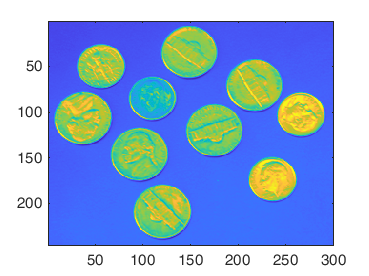

clear all;

I = im2double(imread('coins.png'));
figure; imagesc(I);

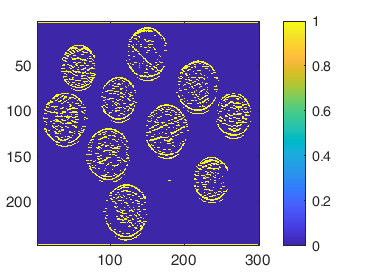

mask_h = [-1 -1 -1; 2 2 2;-1 -1 -1];
J = conv2(I, mask_h, "full");
J = J > .1;
figure; imagesc(J); colorbar; 

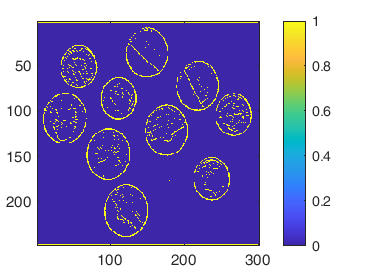

mask = [-1 -1 -1; -1 8 -1;-1 -1 -1];
K = conv2(I, mask, "full");
K = K > .35;
figure; imagesc(K); colorbar;

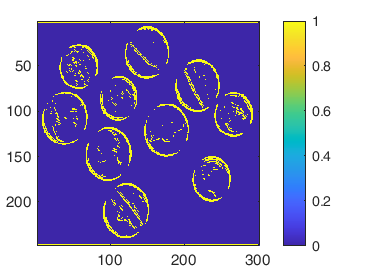


sobel_v = [-1 0 1;-2 0 2;-1 0 1];
sobel_h = [1 2 1;0 0 0;-1 -2 -1];
V = conv2(I, sobel_v, "full");
H = conv2(I, sobel_h, "full");
T = abs(V+H);
T = T>.7;
figure; imagesc(T); colorbar;

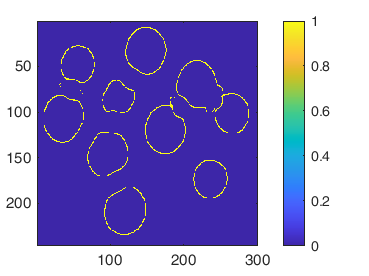


canny = edge(I, "canny", 0.45);
figure; imagesc(canny); colorbar;